# Characteristic Equations 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

When modeling physical systems like circuits, oscillators, or vibrating structures, we often encounter second-order linear differential equations. The **characteristic equation method** provides a systematic approach to solve homogeneous second-order linear ordinary differential equations. In this script, we'll learn how to find characteristic equations, determine their roots, and construct general solutions, with applications in RLC circuits and mass-spring-damper systems.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Background Knowledge

This script expects you to understand the classification of ordinary differential equations. If you need a refresher, please work through the [Classification](matlab:open('./ClassificationSoln.mlx')) script first. You should also be comfortable with solving quadratic equations and working with complex numbers. Basic knowledge of trigonometry and exponential functions will also be helpful.

## The Characteristic Equation Method

Second-order linear ordinary differential equations (ODEs) are very common in applications, because they often describe dynamics involving acceleration, restoring forces, and damping. 

- **Mechanical vibrations**, $m \frac{d^2x}{dt^2} + c\frac{dx}{dt} +kx = F(t)$, 

- where $m$ is a mass, $c$ is a damping constant, $k$ is a spring constant and $F(t)$ is the driving force, and $x(t)$ is the position.

- **RLC electrical circuits**, $L\frac{d^2q}{dt^2} + R\frac{dq}{dt} + \frac{q}{C} = E(t)$, 

- where $L$ is inductance, $R$ is resistance, $C$ is capacitance, $q(t)$ is charge, $\frac{dq}{dt} = I$ is current, and $E(t)$ is the applied voltage source.

- **Control systems**, $\frac{d^2y}{dt^2} + 2\zeta\omega_n\frac{dy}{dt} + \omega_n^2y = Ku(t)$, 

- where $\zeta$ is the damping ratio, $\omega_n$ is the natural frequency, $u(t)$ is the input signal, $K$ is the system gain, and $y(t)$ is the system output.

First, we're going to work through the theory, but we'll look at an RLC circuit and a mass-spring-damper system at the end of this script.

### Standard Form of Second-Order Linear Homogeneous ODEs

The characteristic equation method applies to second-order linear homogeneous differential equations of the form:


$$ay'' + by' + cy = 0$$
 
$$(\star)$$


where $a$, $b$, and $c$ are constants, and $a \neq 0$. Some textbooks suggest a standard form of

$y'' + \left(\frac{b}{a}\right)y' + \left(\frac{c}{a}\right)y = 0$. 

### The Characteristic Equation

To solve equation $(\star)$, we assume a solution of the form $y = e^{rx}$, where $r$ is a constant to be determined. Substituting this into our differential equation:

$y' = re^{rx}$     and      $y'' = r^2e^{rx}$, 

so plugging into the differential equation $(\star)$, this gives us:


$$ar^2e^{rx} + bre^{rx} + ce^{rx} = 0$$


Since $e^{rx} \neq 0$ for any finite value of $x$, we can divide by $e^{rx}$:


$$ar^2 + br + c = 0$$


This quadratic equation in $r$ is called the **characteristic equation** of the differential equation.

### Types of Solutions Based on Roots

As a second order homogeneous ODE, the general solution will be a linear combination of two linearly independent solutions. Conveniently, the quadratic formula tells us that the solutions to the characteristic equation are 

$r_{1,2} = \frac{-b\pm \sqrt{b^2-4ac}}{2a}$.

This gives us two solutions

$y_1 = e^{r_1x}$ and $y_2=e^{r_2x}$, 

right? There are three scenarios that can occur: distinct real roots, repeated roots, and complex conjugate roots. Perhaps surprisingly, as long as our roots are not repeated, the process of identifying our solution will be very much the same! The challenge if $r_1 = r_2$ is that we don't have two linearly independent solutions! We can check how to build a second independent solution when we get there. 

Let's classify the cases according to the discriminant $\Delta = b^2 - 4ac$, and work through them one at a time.

#### Case 1: Two Distinct Real Roots (Δ>0)

If $r_1$ and $r_2$ are distinct real roots, we have two linearly independent solutions $y_1 = e^{r_1x}$ and $y_2 = e^{r_2x}$ so the general solution is:


$$y(x) = c_1e^{r_1x} + c_2e^{r_2x}$$


**Step-by-Step Example**

Consider the differential equation: $y'' - 5y' + 6y = 0$.

**Step 1:** Write the characteristic equation by applying the method described above.


$$r^2 - 5r + 6 = 0$$


**Step 2:** Solve the characteristic equation for the roots.


$$(r - 2)(r - 3) = 0$$


So $r_1 = 2$ and $r_2 = 3$ (distinct real roots).

**Step 3:** Identify two linearly independent solutions to the homogeneous differential equation: $y_1(x) = e^{2x}$ and $y_2(x)  = e^{3x}$.

**Step 4:** Write the general solution as a general linear combination of the two linearly independent homogeneous solutions. 


$$y(x) = c_1e^{2x} + c_2e^{3x}$$


 **Exercise 1. Distinct real roots**

 
[diffeq1,Problem1] = GenerateProblem("real");

a) What is the characteristic polynomial?

syms x
CharPol = Problem1.LHS*[x^2;x;1]==0;  
CheckCharacteristicPolynomial(CharPol,Problem1)

b) What are the roots of this polynomial?

r1 = Problem1.roots(1);
r2 = Problem1.roots(2);  
CheckRoots(r1,r2,Problem1)

c) What is the general solution to the differential equation? Use `C1` and `C2` for the general coefficients. Remember that $e^{rx}$ is `exp(r*x)` in MATLAB.

syms x C1 C2 y(x)
GenSol = dsolve(diffeq1.homog);  
CheckGeneralSolution(GenSol,diffeq1)

#### Case 2: One Repeated Real Root (Δ=0)

This is a problem, because if we followed the patterns in Case 1 we would have

$y(x) = c_1e^{rx}+c_2e^{rx} = ce^{rx}$,

because the solutions that we found are (very clearly!) linearly *dependent.* How can we find another linearly independent solution? We know we need a function where the derivative will look like a multiple of itself, so let's try using a test function 


$$y_{\text{test}} = xe^{rx}$$
 

with derivatives 

$y_{\text{test}}' = e^{rx}+rxe^{rx}$ ,

$y_{\text{test}}'' = 2re^{rx} + r^2xe^{rx}$. 

Plugging in, we have:

$a\left(2re^{rx}+r^2xe^{rx}\right) + b\left(e^{rx}+rxe^{rx}\right) + c\left(xe^{rx}\right) = (2ar+b)e^{rx} + \left(ar^2+br+c\right)xe^{rx}$.

Now, $(ar^2+br+c)=0$, but what about that $(2ar+b)$ term? Remember that we know $\Delta = b^2-4ac = 0$, which means that $r = \frac{-b}{2a}$, and thus $2ar+b = -b+b = 0$. This gives us a second, linearly independent, solution $y_2 = xe^{rx}$. Therefore, if $r$ is a repeated root, the general solution is:


$$y(x) = (c_1 + c_2x)e^{rx}$$


**Step-by-Step Example**

Consider the differential equation: $y'' - 4y' + 4y = 0$.

**Step 1:** Write the characteristic equation by applying the method described above.


$$r^2 - 4r + 4 = 0$$


**Step 2:** Solve the characteristic equation for the roots.


$$(r - 2)(r - 2) = 0$$


So $r_1 = 2$ and $r_2 = 2$ (repeated real roots).

**Step 3:** Identify two linearly independent solutions to this homogeneous differential equation: $y_1(x) = e^{2x}$ and $y_2(x) = xe^{2x}$. 

**Step 4:** Write the general solution as any linear combination of the two linearly independent homogeneous solutions. 


$$y(x) = c_1e^{2x} + c_2xe^{2x} = (c_1+c_2x)e^{2x}$$


 **Exercise 2. Repeated Roots**

 
[diffeq2,Problem2] = GenerateProblem("repeated");

a) What is the characteristic polynomial?

syms x
CharPol2 = Problem2.LHS*[x^2;x;1]==0;  
CheckCharacteristicPolynomial(CharPol2,Problem2)

b) What are the roots of this polynomial?

r12 = Problem2.roots(1);
r22 = Problem2.roots(2);  
CheckRoots(r12,r22,Problem2)

c) What is the general solution to the differential equation? Use `C1` and `C2` for the general coefficients. Remember that $e^{rx}$ is `exp(r*x)` in MATLAB.

syms x C1 C2 y(x)
GenSol2 = dsolve(diffeq2.homog);  
CheckGeneralSolution(GenSol2,diffeq2) 

#### Case 3: Complex Conjugate Roots (Δ<0)

If the roots are $r = \alpha \pm \beta i$, our solutions are $y_1 = e^{(\alpha+\beta i)x}$ and $y_2 = e^{(\alpha-\beta i)x}$. Following the earlier pattern, our general solution is:

$y = c_1e^{(\alpha+\beta i)x}+c_2e^{\alpha-\beta i)x}$.

These are linearly independent functions, but can we recombine these terms to look more familiar? Recall Euler's formula: $e^{i\theta} = \cos(\theta)+i\sin(\theta)$.  


$$y = c_1e^{(\alpha+\beta i)x}+c_2e^{\alpha-\beta i)x}$$



$$y = e^{\alpha x}\left(c_1e^{\beta xi}+c_2e^{-\beta xi}\right)$$



$$y = e^{\alpha x}\left(c_1(\cos(\beta x)+i\sin(\beta x))+c_2(\cos(\beta x)-i\sin(\beta x))\right)$$



$$y = e^{\alpha x}\left((c_1+c_2)\cos(\beta x)+i(c_1-c_2)\sin(\beta x)\right)$$


and finally, remember that $c_1$ and $c_2$ are simply general constants so the new combinations $c_1+c_2$ and $i(c_1-c_2)$ are also arbitrary constants. It is a good reminder that "arbitrary" does not mean *real.* 

Therefore, the general solution can be written as:


$$y(x) = e^{\alpha x}(c_1\cos(\beta x) + c_2\sin(\beta x))$$


or


$$y(x) = c_1e^{(\alpha+\beta i)x}+c_2e^{\alpha-\beta i)x}$$


whichever is more convenient.

**Step-by-Step Example**

Consider the differential equation: $5y'' - 4y' + y = 0$.

**Step 1:** Write the characteristic equation by applying the method described above.


$$5r^2- 4r + 1 = 0$$


**Step 2:** Solve the characteristic equation for the roots.


$$r = \frac{-(-4)\pm \sqrt{(-4)^2-4(5)(1)}}{2(5)}$$



$$r = \frac{4\pm \sqrt{-4}}{10}$$


So $r_1 = \frac{2}{5}+\frac{i}{5}$ and $r_2 = \frac{2}{5}-\frac{i}{5}$ (complex conjugate roots).

**Step 3:** Identify two linearly independent solutions to this homogeneous differential equation: $y_1(x) = e^{\frac{2x}{5}}\sin\left(\frac{x}{5}\right)$ and $y_2(x) = e^{\frac{2x}{5}}\cos\left(\frac{x}{5}\right)$. 

**Step 4:** Write the general solution as any linear combination of the two linearly independent homogeneous solutions. 


$$y(x) = c_1e^{\frac{2x}{5}}\sin\left(\frac{x}{5}\right) + c_2e^{\frac{2x}{5}}\cos\left(\frac{x}{5}\right)$$


 **Exercise 3. Complex Roots**

 
[diffeq3,Problem3] = GenerateProblem("complex");

a) What is the characteristic polynomial?

syms x
CharPol3 = Problem3.LHS*[x^2;x;1]==0;  
CheckCharacteristicPolynomial(CharPol3,Problem3)

b) What are the roots of this polynomial?

r13 = Problem3.roots(1);
r23 = Problem3.roots(2);  
CheckRoots(r13,r23,Problem3)

c) What is the general solution to the differential equation? Use `C1` and `C2` for the general coefficients. Remember that $e^{rx}$ is `exp(r*x)` in MATLAB. Use the real functional form with sines and cosines.

syms x C1 C2 y(x)
GenSol3 = dsolve(diffeq3.homog);  
CheckGeneralSolution(GenSol3,diffeq3)

 **Exercise 4.** Apply the methods you have learned to solve the following problem.

 
[diffeq4,Problem4] = GenerateProblem("any");

a) What is the characteristic polynomial?

syms x
CharPol4 = Problem4.LHS*[x^2;x;1]==0;  
if exist("Problem4","var")
    CheckCharacteristicPolynomial(CharPol4,Problem4)
else
    warning("You must generate a problem before you can solve it.")
end

b) What are the roots of this polynomial?

r14 = Problem4.roots(1);
r24 = Problem4.roots(2);  
if exist("Problem4","var")
    CheckRoots(r14,r24,Problem4)
else
    warning("You must generate a problem before you can solve it.")
end

c) Which case applies to this polynomial?

type = Problem4.type;

if exist("Problem4","var")
    CheckType(type,Problem4)
else
    warning("You must generate a problem before you can solve it.")
end

d) What is the general solution to the differential equation? Use `C1` and `C2` for the general coefficients. Remember that $e^{rx}$ is `exp(r*x)` in MATLAB. Use the real functional form with sines and cosines.

syms x C1 C2 y(x)
GenSol4 = dsolve(diffeq4.homog);  
if exist("diffeq4","var")
    CheckGeneralSolution(GenSol4,diffeq4)
else
    warning("You must generate a problem before you can solve it.")
end

##  **Application** 1: RLC Circuits

An RLC circuit consists of a resistor (R), inductor (L), and capacitor (C) connected in series. 

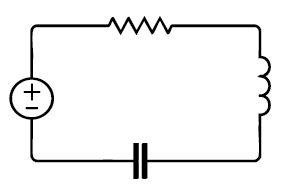

The voltage across the capacitor satisfies the differential equation:


$$L\frac{d^2q}{dt^2} + R\frac{dq}{dt} + \frac{1}{C}q = 0$$


where $q(t)$ is the charge on the capacitor.

Dividing by $L$, we get the standard form:


$$\frac{d^2q}{dt^2} + \frac{R}{L}\frac{dq}{dt} + \frac{1}{LC}q = 0$$


The characteristic equation can be written as: 

$r^2 + \frac{R}{L}r + \frac{1}{LC} = 0$.

The discriminant is: 

$\Delta = \left(\frac{R}{L}\right)^2 - \frac{4}{LC}$.

  **Try**. **Interactive RLC Circuit Analysis**

The behavior of the circuit depends on the discriminant. Can you find values for $L$, $R$, and $C$ that result in a positive discriminant? A negative discriminant? A zero discriminant? Explore how different circuit parameters affect the response:

L_val = 3.5; % H
R_val = 0.5*1000;  % Ω
C_val = 0.5*1e-6;   % F   
show_theory = true;
AnalyzeRLCCircuit(L_val, R_val, C_val, show_theory);

 **Reflect**. Did you notice that the solutions to systems with positive, negative, and zero discriminant have names? Why do you think a system with negative discriminant is called "underdamped"? Or a system with a positive discriminant "overdamped"? 

##  Application 2: Mass-Spring-Damper Systems

A mass-spring-damper system is governed by Newton's second law:


$$m\frac{d^2x}{dt^2} + c\frac{dx}{dt} + kx = 0$$


where $m$ is mass, $c$ is the damping content, and $k$ is the spring constant. The value $x$ tracks the position of the mass along a line at time $t$.

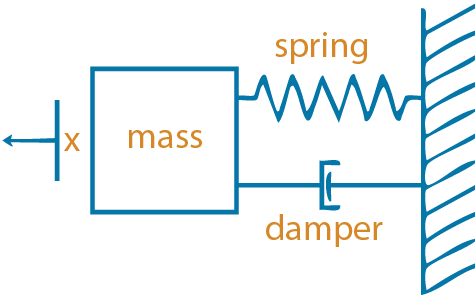

Dividing by $m$, we get: 

$\displaystyle \frac{d^2x}{dt^2} + \frac{c}{m}\frac{dx}{dt} + \frac{k}{m}x = 0$.

The characteristic equation is: 

$r^2 + \frac{c}{m}r + \frac{k}{m} = 0$.

The discriminant is:

$\Delta = \frac{c^2}{m^2}-\frac{4k}{m}$.

### System Behavior

  **Try**. **Interactive Mass-Spring-Damper Analysis**

Similar to the RLC circuit, the behavior depends on the discriminant. Can you find an underdamped system? An overdamped system? A critically damped system? Explore different mechanical system parameters:

m_val = 75; % kg
c_val = 38; % Ns/m
k_val = 521; % N/m
x0_val = -1;
v0_val = 0;   
show_theory_msd = true;
AnalyzeMassSpringDamper(m_val, c_val, k_val, x0_val, v0_val, show_theory_msd);

 **Reflect**. The phase portrait plots the path of a solution in phase space, that is position versus velocity (or momentum). This view can be a convenient way to see if a solution is converging to a steady state or diverging to, for any real system, something breaking. For this system, we know that $x(0) = 0$, $\dot{x}(0)=0$ is an equilibrium solution. If we start with a mass sitting still at the resting distance for the spring, it will just sit there forever until something changes. Because of the damper, this system is always going to be approaching that steady state. Can you think of some values to change so that it would not?

## Further Exploration

To learn how to work with these types of equations symbolically in MATLAB, you could take the beginning of the [Introduction to Symbolic Math with MATLAB](https://matlabacademy.mathworks.com/v1/portal.html?course=symbolic) course, just up through "Define and Solve Symbolic Equations" and then skip to "Solving Ordinary Differential Equations" in the Calculus with Symbolic Math chapter.

There is more discussion of phase portraits in the courseware on [Qualitative Analysis of ODEs](https://www.mathworks.com/matlabcentral/fileexchange/95513-qualitative-analysis-of-odes).

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function AnalyzeRLCCircuit(L, R, C, show_theory)
% Calculate characteristic equation parameters
a = 1;
b = R/L;
c = 1/(L*C);

% Calculate discriminant
discriminant = b^2 - 4*a*c;

% Calculate roots
syms t
roots = solve([a b c]*[t^2;t;1]==0);
r1 = roots(1);
r2 = roots(2);
if discriminant > 0
    case_name = 'Overdamped';
elseif discriminant == 0
    case_name = 'Critically Damped';
else
    alpha = real(r1);
    beta = abs(imag(r1));
    case_name = 'Underdamped';
end

% Calculate response (assuming q(0) = 1, q'(0) = 0)
syms q(t) t
Dq = diff(q,t);
diffeq = a*diff(q,t,2)+b*Dq + c*q == 0;
qSoln = dsolve(diffeq,[q(0)==1 Dq(0)== 0]);

% Create time vector
tVals = linspace(0, 20*L/R, 1000);
qVals = subs(qSoln,t,tVals);

figure
tiledlayout(2,1)

nexttile
plot(tVals, qVals, "-", LineWidth=2)
title("RLC Circuit Response - " + case_name)
xlabel("Time (s)")
ylabel("Charge q(t)")
grid on
ylim(double([min(qVals)-0.1*range(qVals), max(qVals)+0.1*range(qVals)]))

nexttile
% Show parameter relationships
bar(1, R/L, FaceColor="r", FaceAlpha=0.7)
hold on
bar(2, 2*sqrt(1/(L*C)), FaceColor="g", FaceAlpha=0.7)
bar(3, discriminant, FaceColor="b", FaceAlpha=0.7)
hold off

xticks([1 2 3])
xticklabels(["R/L", "2/√(LC)", "Δ"])
ylabel("Value")
title("Circuit Parameters")
grid on
legend("Damping", "Natural Freq", "Discriminant",Location="southwest")

% Display analysis
if show_theory
    fprintf('\n--- RLC Circuit Analysis ---\n')
    fprintf('L = %.2f H, R = %.2f kΩ = %.0f Ω , C = %.3f µF = %.2f * 1e-7 F\n', L, R/1000,R, 1e6*C, 1e7*C)
    fprintf('Characteristic equation: r² + %.3fr + %.3f = 0\n', b, c)
    fprintf("Damping: %.3f\nNatural frequency: %.3f\n",R/L,2/sqrt(L*C))
    fprintf('Discriminant: %.3f\n', discriminant)
    fprintf('System type: %s\n', case_name)

    if discriminant >= 0
        fprintf('Roots: r₁ = %.3f, r₂ = %.3f\n', r1, r2)
    elseif show_theory
        fprintf('Complex roots: r = %.3f ± %.3fi\n', alpha, beta)
    end

    fprintf("Assume q(0)=1 and q'(0)=0.\n")
    % Display the differential equation solution
    fprintf('Differential equation solution: q(t) = %s\n', char(qSoln))
end
end

function AnalyzeMassSpringDamper(m, c, k, x0, v0, show_theory)
% Calculate characteristic equation parameters
a = 1;
b = c/m;
c_coeff = k/m;

% Calculate discriminant
discriminant = b^2 - 4*a*c_coeff;

% Calculate natural frequency and damping ratio
omega_n = sqrt(k/m);
zeta = c/(2*sqrt(k*m));

syms t x(t)
roots = solve([a b c_coeff]*[t^2;t;1]==0);
r1 = roots(1);
r2 = roots(2);
Dx = diff(x,t);
xEqn = dsolve(a*diff(x,t,2)+b*Dx+c_coeff*x==0,[x(0)==x0 Dx(0)==v0]);
tVals = linspace(0, 10/omega_n, 1000);
xVals = subs(xEqn,t,tVals);

% Calculate roots and response
if discriminant > 0
    % Overdamped
    case_name = "Overdamped";
elseif abs(discriminant) < 1e-10
    % Critically damped
    case_name = "Critically Damped";
else
    % Underdamped
    case_name = "Underdamped";
    alpha = real(r1);
    beta = abs(imag(r1));
end

figure(Position=[1 1 1100 500])
tiledlayout(2,2)

nexttile
plot(tVals, xVals, "-", LineWidth=2)
hold on
scatter(0,x0,35,"filled","o",SeriesIndex=2)
hold off
title(sprintf("Mass-Spring-Damper - %s", case_name))
xlabel("Time (s)")
ylabel("Displacement x(t)")
grid on
legend("Response", "Initial Position")

nexttile
% Phase portrait (velocity vs position)
if length(tVals) > 1
    vEqn = diff(xEqn,t);
    vVals = subs(vEqn,t,tVals);
    plot(xVals, vVals, "-", LineWidth=1.5,SeriesIndex=5)
    hold on
    scatter(x0, v0, 35, "filled", SeriesIndex=2)
    scatter(0, 0, 35, "filled", SeriesIndex="none")
    hold off
end
xlabel("Position x")
ylabel("Velocity dx/dt")
title("Phase Portrait")
grid on
legend("Trajectory", "Initial State", "Equilibrium",Location="best")

nexttile
% System parameters
bar(1, omega_n, SeriesIndex=1, FaceAlpha=0.7)
hold on
bar(2, zeta, SeriesIndex=2, FaceAlpha=0.7)
bar(3, discriminant, SeriesIndex=3, FaceAlpha=0.7)
hold off

xticks([1 2 3])
xticklabels({"ωₙ", "ζ", "Δ"})
ylabel("Value")
title("System Parameters")
grid on

nexttile
% Energy analysis (for underdamped case)
if discriminant < 0
    KE = 0.5*m*vVals.^2;
    PE = 0.5*k*xVals.^2;
    Total = KE + PE;

    plot(tVals, KE, "-", "LineWidth", 1.5, SeriesIndex=2)
    hold on
    plot(tVals, PE, "-", "LineWidth", 1.5, SeriesIndex=1)
    plot(tVals, Total, "--", "LineWidth", 2, SeriesIndex="none")
    hold off
    xlabel("Time (s)");
    ylabel("Energy");
    title("Energy vs Time");
    legend("Kinetic", "Potential", "Total");
    grid on;
else
    msg = ["Energy plot" "available for" "underdamped case"];
    text(0.5, 0.5, msg, ...
        "HorizontalAlignment", "center", "FontSize", 12);
    xlim([0 1]); ylim([0 1]);
    axis off
    title("Energy Analysis");
end

% Display analysis
if show_theory
    fprintf("\n--- Mass-Spring-Damper Analysis ---\n");
    fprintf("m = %.2f kg, c = %.2f N·s/m, k = %.2f N/m\n", m, c, k);
    fprintf("Initial conditions: x₀ = %.2f m, v₀ = %.2f m/s\n", x0, v0);
    fprintf("Natural frequency: ωₙ = %.3f rad/s\n", omega_n);
    fprintf("Damping ratio: ζ = %.3f\n", zeta);
    fprintf("Discriminant: %.3f\n", discriminant);
    fprintf("System type: %s\n", case_name);

    if discriminant >= 0
        fprintf("Characteristic roots: r₁ = %.3f, r₂ = %.3f\n", r1, r2);
    else
        fprintf("Complex roots: r = %.3f ± %.3fi\n", alpha, beta);
        fprintf("Damped frequency: ωd = %.3f rad/s\n", beta);
    end

    % Display the differential equation solution
    fprintf("Differential equation solution: x(t) = %s\n", char(xEqn));
end
end


function [diffeq,RHS] = GenerateProblem(type)
arguments
    type (1,1) string {mustBeMember(type,["real","repeated","complex","any"])}
end

if type == "any"
    opts = ["real" "repeated" "complex"];
    idx = randi(3);
    choice = opts(idx);
else
    choice = type;
end

syms x y(x)

[LH,a,v] = CreatePolynomial();

switch choice
    case "real"
        while v(1) == v(2)
            [LH,~,v] = CreatePolynomial();
        end
    case "repeated"
        LH = a*poly([v(1) v(1)]);
    case "complex"
        Delta1 = v(1)^2 - 4*a*v(2);
        Delta2 = v(1)^2 + 4*a*v(2);
        while Delta1 >= 0 && Delta2 >= 0
            [~,a,v] = CreatePolynomial();
            Delta1 = v(1)^2 - 4*a*v(2);
            Delta2 = v(1)^2 + 4*a*v(2);
        end
        if Delta1 < 0
            LH = [a v];
        else
            LH = [-a v];
        end
end
g = 0;
diffeq = struct("full",LH(1)*diff(y,x,2)+LH(2)*diff(y,x)+LH(3)*y == g,"homog",LH(1)*diff(y,x,2)+LH(2)*diff(y,x)+LH(3)*y == 0);
displayFormula(['"Solve "'; "diffeq.homog"])
roots = solve(LH*[x^2;x;1]);
RHS = struct("type",choice,"roots",roots,"LHS",LH);
end

function [LH,a,v] = CreatePolynomial()
v = randi(11,[1 2])-6;
a = (randi(2,1)-1)*(randi(11,1)-6);
if a == 0
    a = 1;
end
LH = a*poly(v);
end

function CheckCharacteristicPolynomial(CharPol,RHS)
syms x
CharPolSoln = RHS.LHS*[x^2;x;1] == 0;
if isequal(CharPol,CharPolSoln)
    disp("Correct! The characteristic polynomial is:")
    displayFormula("CharPolSoln")
elseif isequal(CharPol,x==0)
    disp("This is the default solution. The characteristic polynomial of a" + newline + ...
        "second order linear ODE will be quadratic.")
elseif solve(CharPol) == RHS.roots
    disp("Incorrect. Did you remember to define an equation with == 0?")
else
    disp("Incorrect. Please check your coefficients and try again.")
end
end

function CheckRoots(r1,r2,RHS)
Roots1 = [r1; r2];
Roots2 = [r2; r1];
if all(Roots2 == RHS.roots) || all(Roots1 == RHS.roots)
    syms r
    if RHS.type == "repeated"
        displayFormula(['"Correct! The solution is "' "r == r1" '" twice!"'])
    else
        displayFormula(['"Correct! The roots are "' "r_1==r1" '", and "' "r_2 == r2" '"."'])
    end
elseif all(abs(Roots1-RHS.roots)<1e-4)
    syms r
    root1 = RHS.roots(1);
    root2 = RHS.roots(2);
    if RHS.type == "repeated"
        displayFormula(['"Correct! The solution is "' "r == root1" '" twice!"'])
    else
        displayFormula(['"Correct! The roots are "' "r_1==root1" '", and "' "r_2 == root2" '"."'])
    end
elseif all(abs(Roots2-RHS.roots)<1e-4)
    syms r
    root1 = RHS.roots(1);
    root2 = RHS.roots(2);
    if RHS.type == "repeated"
        displayFormula(['"Correct! The solution is "' "r == root1" '" twice!"'])
    else
        displayFormula(['"Correct! The roots are "' "r_1==root2" '", and "' "r_2 == root1" '"."'])
    end
elseif all(Roots1 == [0;0])
    disp("This is the default. Please compute and enter the roots of the characteristic polynomial.")
elseif all(-Roots2 == RHS.roots) || all(-Roots1 == RHS.roots)
    disp("Incorrect. You appear to have your signs backwards. Please check your computations.")
elseif any(Roots2 == RHS.roots) || any(Roots1 == RHS.roots)
    disp("One root is correct, but the other is not. Please check your computations.")
else
    disp("No, those roots are incorrect. Please check your computations and try again.")
end
end

function CheckType(type,Problem)
if Problem.type == type
    disp("Correct, this problem has " + type + " roots.")
elseif type == "unknown"
    disp("This is the default value. Once you generate a problem, there will certainly be known roots.")
else
    disp("Incorrect. Please try again. What are the roots of this characteristic equation?")
end
end

function CheckGeneralSolution(GenSol,diffeq)
syms x C1 C2 y(x) coeff1 coeff2
GenSol = subs(GenSol,[C1 C2],[coeff1 coeff2]);
GenSol1a = subs(GenSol,[coeff1 coeff2],[C1 C2]);
GenSol2a = subs(GenSol,[coeff1 coeff2],[C2 C1]);
GenSol1b = subs(GenSol,[coeff1 coeff2],[C1 -C2]);
GenSol2b = subs(GenSol,[coeff1 coeff2],[C2 -C1]);
GenSolAns = dsolve(diffeq.homog);
if isAlways(GenSol1a==GenSolAns,"Unknown","false") || isAlways(GenSol2a==GenSolAns,"Unknown","false") ...
        || isAlways(GenSol1b==GenSolAns,"Unknown","false") || isAlways(GenSol2b==GenSolAns,"Unknown","false") ...
        || isAlways(-GenSol1a==GenSolAns,"Unknown","false") || isAlways(-GenSol2a==GenSolAns,"Unknown","false") ...
        || isAlways(-GenSol1b==GenSolAns,"Unknown","false") || isAlways(-GenSol2b==GenSolAns,"Unknown","false")
    disp("Correct! The solution is: ")
    displayFormula("y(x) == GenSol1a")
elseif isAlways(GenSol1a == C1*x + C2*exp(4*x),"Unknown","false")
    disp("This is the default solution.")
elseif ~isreal(diff(GenSol,x))
    displayFormula(['"You wrote "' "y(x) == GenSol" '" but your answer should not involve complex values."'])
    displayFormula('"Please express your solution with only real values. Use sines and cosines if necessary."')
else
    disp("Incorrect. Please try again.")
end
end